# Damped Pendulum 

## 
$$\theta^¨ \;\left(t\right)=-\mu \theta^˙ \;\left(t\right)-\frac{g}{L}\;\mathrm{sin}\left(\theta \left(t\right)\right)$$
         
$$\overrightarrow{r} \left(t\right)=\left\lbrack \begin{array}{c}
V_0 \;\cos \left(\theta_0 \;t\right)\\
-\frac{1}{2}{\textrm{gt}}^2 +V_0 \sin \left(\theta_0 t\right)
\end{array}\right\rbrack$$


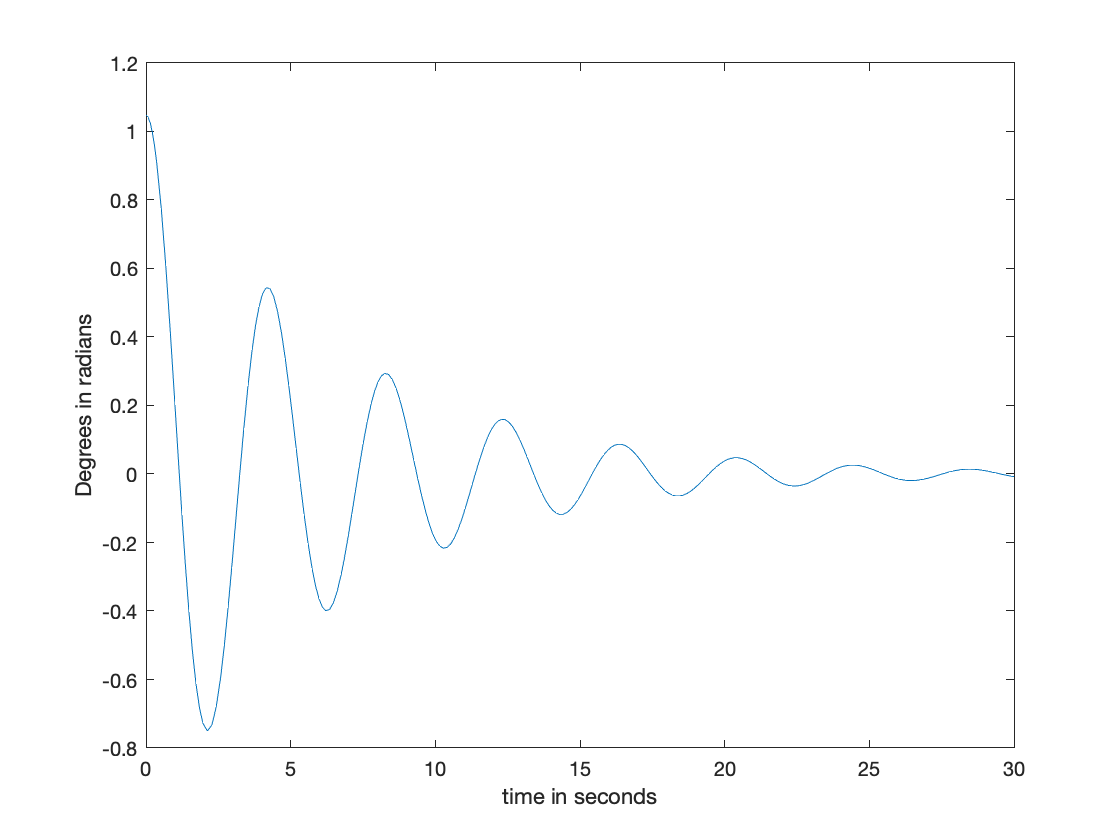

g = 9.8;
L = 2;
mu = 0.1;

theta_0 = pi/3;
theta_dot_0 = 0;

[t, y] = ode45(@ODE45PendWDrag, [0, 30], [theta_0; theta_dot_0]);
plot(t, y(:,1))
xlabel('time in seconds')
ylabel('Degrees in radians')

# Driven Damped Pendulum

$m L^{2} \ddot{\phi}=-b L^{2} \dot{\phi}-m g L \sin \phi+L F(t)$       ***where  ***    $F(t)=F_{\mathrm{o}} \cos (\omega t)$


$$\ddot{\phi}+\frac{b}{m} \dot{\phi}+\frac{g}{L} \sin \phi=\frac{F_{\mathrm{o}}}{m L} \cos \omega t$$
       
$$\to$$
      
$$\frac{b}{m}=2 \beta$$
        
$$\frac{g}{L}=\omega_{o}^{2}$$
       
$$\gamma=\frac{F_{\mathrm{o}}}{m L \omega_{\mathrm{o}}^{2}}=\frac{F_{\mathrm{o}}}{m g}$$



$$\ddot{\phi}+2 \beta \dot{\phi}+\omega_{0}^{2} \sin \phi=\gamma \omega_{0}^{2} \cos \omega t$$


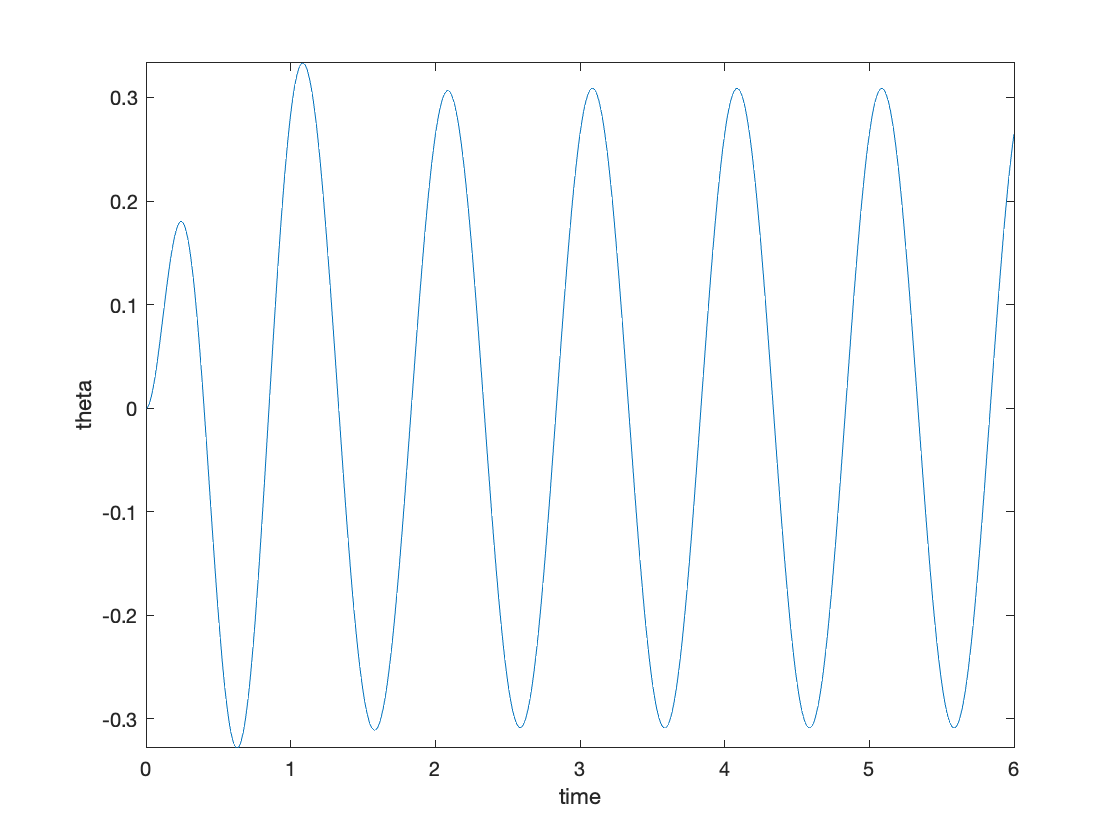

syms tau omega omega_0 gamma phi(t) beta 

dphi = diff(phi, t);
ddphi = diff(phi, t, 2);
equ = ddphi + 2*beta*dphi + omega_0^2*sin(phi) == gamma*omega_0^2*cos(omega*t);
% since gamma << 1, we expect phi to remain small at all times, 
% so sin(phi) ~= phi
equ = subs(equ, sin(phi), phi);

% Replacing parameters with simple values
tau = 1;
old = [omega, omega_0, beta, gamma];
omega = (2*pi)/tau;
omega_0 = 1.5*omega;
beta = omega_0/4;
gamma = 0.2; 
new = [omega, omega_0, beta, gamma];
equ = subs(equ, old, new);

conds = [dphi(0) == 0, phi(0) == 0];
q = dsolve(equ, conds);
% Plotting first 6 seconds of motion
fplot(q, [0,6])
xlabel("time")
ylabel("theta")


$$\sin \phi \approx \phi-\frac{1}{6} \phi^{3}$$
     
$$\to$$
      
$$\ddot{\phi}+2 \beta \dot{\phi}+\omega_{\circ}^{2}\left(\phi-\frac{1}{6} \phi^{3}\right)=\gamma \omega_{\circ}^{2} \cos \omega t$$


syms tau omega omega_0 gamma phi(t) beta 

dphi = diff(phi, t);
ddphi = diff(phi, t, 2);
equ = ddphi + 2*beta*dphi + omega_0^2*sin(phi) == gamma*omega_0^2*cos(omega*t);
equ = subs(equ, sin(phi), (phi - (1/6)*phi^3))

$$equ(t) = \frac{\partial^{2}}{\partial t^{2}}\phi \left(t\right)+2\,\beta \,\frac{\partial }{\partial t}\phi \left(t\right)+\left(\phi \left(t\right)-\frac{{\phi \left(t\right)}^{3}}{6}\right)\,{\omega_{0}}^{2}=\gamma \,{\omega_{0}}^{2}\,\cos\left(\omega \,t\right)$$

syms A B delta
phi =  A*cos(omega*t - delta) + B*cos(3*omega*t - 3*delta);
equ = subs(equ, sym('phi'), phi);
simplify(equ);

% Replacing parameters with simple values
tau = 1;
old = [omega, omega_0, beta, gamma];
omega = (2*pi)/tau;
omega_0 = 1.5*omega;
beta = omega_0/4;
gamma = 0.9; 
new = [omega, omega_0, beta, gamma];
equ = subs(equ, old, new);

conds = [dphi(0) == 0, phi(0) == 0];

%[V] = odeToVectorField(equ)
%M = matlabFunction(V,'vars', {'t','Y'})
%sol = ode45(M,[0 6], [0, 0]);
%fplot(@(x)deval(sol,x,1), [0, 6])


